# Spectrum Features Quick Viewer +Table Maker（一般振動データrD版）

#### 一般化版とスピナー専用版の異なりは、スピナー版がｘ軸のみに対して、一般化版はｘｙｚなど３軸を持つ場合がある。

#### 注：各フィールドは先頭が、時刻相当、他振動データとみなして２列目から計算しているので、それ以外のデータを入れている場合は、前もって削除しておくこと。

####     {'xDate'}    {'SN'}    {'Ax'}    {'Az'}    {'Ay'}    {'CT'}　など、XDate以外に***SN***などを入れている場合

- 2020/08/12 x

- 2020/09/11 FOXCON用に修正 (注:SKとPS部分は未完)

- 2021/03/01 スピナー寿命確認用に修正

- input : rD (またはxTableをrDにrenameしたもの)

- output: TFS (feature table)

振動データを各変数に持つ、xTable, rD使用バージョン

- xTableは、P01_VibrationCSV2MAT.mlx によって測定CSVデータから時系列テーブル化されていること。

- 本スクリプトは、rDをベースに計算するので、rDがない場合は、XTableから名前を変えて作成しておくこと。rDは計算用のワークテーブルを意味する。rD = xTable として問題ない。

- rD中のどの変数を表示するか、設定すること。

- rDの構造は、例えば以下の通り

- 127393x1 timetable	127393x1 timetable	127393x1 timetable	127393x1 timetable	127393x1 timetable

- 217289x1 timetable	217289x1 timetable	217289x1 timetable	217289x1 timetable	217289x1 timetable

- 218382x1 timetable	218382x1 timetable	218382x1 timetable	218382x1 timetable	218382x1 timetable

- ：

振動データから特徴量を確認するスクリプト。ここですべての特徴量を計算しながら、MATファイルとは別に特徴量テーブルを作成する。XYZ軸など、複数の振動データがある場合は、各々に対して特徴量を計算する必要があるため、単一特徴量としてMATファイルに保存するのは得策ではない。

大量のデータを表示するとメモリ圧迫する可能性高いので、表示するかどうか設定する

#### バグFIX

- 2020/10/02 FFTで表示周波数を設定する場合のインデックスを整数にする関数にuint32からroundを使用する

## 変数設定

データのサンプリング周波数などは特定して、指定しておくこと

% rD = table2timetable(rD)
% clear
fs = 25600         % FOXCONN Sampling frequency

fs = 25600

% fs = 50000         % Sampling frequency
T = 1/fs           % Sampling period

T = 3.9063e-05

%t = (0:L-1) * T;

%FFT用のデータ保存テーブルを作成しない場合は、Cellで作成される
%空のテーブルに変数名を入れることはできない↓ので、最後に手作業で追加する
% TFFT = table('VariableNames',{'FFTFx','FFTFy','FFTFz','FFTVx','FFTVy','FFTVz','FFTAE','FFTFxMax','FFTFyMax','FFTFzMax' ...
%    ,'FFTVxMax','FFTVyMax','FFTVzMax','FFTAEMax' });
% variableNames = TFFTTest1.Properties.VariableNames %変数名の保存
% TFFT.Properties.VariableNames = variableNames 
prompt = {'Run Mode FFT/SK/PS/RAW:','Plot (Y/N):', 'Max frequency 50000:', 'Time SP_TIME/xTime:' };
dlgtitle = 'Input';
dims = [1 1 1 1];
definput = {'FFT','Y','25000','SP_TIME'};
answer = inputdlg(prompt,dlgtitle,dims,definput);
if numel(answer) == 0
    return
end
runmode = answer{1}

runmode = 'FFT'

answer{2}

ans = 'Y'

%bs = str2num(answer{2});
%timeaxis = answer{4};
fst = fs/str2double(answer{3})     % 100;   % Target fs (Hz) range on plot　描画用周波数レンジ

fst = 1.0240

wc = 128                           % 128 でスペクトル尖度を計算するウィンドウサイズ

wc = 128

fsk = round(wc*8*str2double(answer{3})/fs)  %SKの表示用周波数範囲

fsk = 1000

day = 1;                             %日時で変化するデータに使用
%TSK = table;                        %SK用のデータ保存テーブル


if exist("rD","var") == false
    load ("TrD.mat","rD");  %rD = running data table
end
Maxct = numel(rD{:,1});                     %分析の最大行数設定
Maxfld = numel(rD.Properties.VariableNames) %分析の最大列数（分析変数の数）設定

Maxfld = 17

## データの読込と処理

#### % rD変数の数だけ回す、ただし、1行目はSNなどに使用される前提で2から

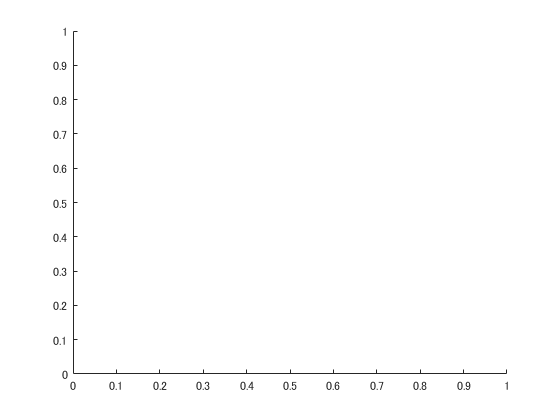

この型の変数では中かっこのインデックス付けはサポートされていません。

for ctfld = 2:Maxfld          % XYZなど振動変数が複数あった場合
    if answer{2} == "Y"       % 表示する場合
        figure;
        colors = parula(50);
        hold on
    end

    for ct = 1:Maxct        %行数、測定数
        %データ読み込みの変数指定方法参考
        %gsdata = rD(ct,"Vx");         %. gsdata = rD(ct,'Value')
        %gs = rD(ct,"Vx").Vx{1};    %. gs = gsdata.Value{1}
        %g = rD(ct,"Vx").Vx{1}.Vx;
        %gs.Properties.SampleRate = fs;

        gs = rD(ct,ctfld).(1){1};    %. gs = gsdata.Value{1}
        g = rD(ct,ctfld).(1){1}.(1);    % for で回せるように変数名ではなく、添字で指定、↑の記載と同じ意味
%        thour = rD(ct,"xDate").xDate;         % Y軸
        thour = rD(ct,1).(1);         % Y軸
        L = numel(g);                   % Length of signal 100000、測定長さが異なる場合の備え
        switch runmode
            case "RAW"
                ls = 100;              % 表示間隔 
                ysn = ct*ones(size(gs.Time));
                p=plot3(gs.Time(1:ls:end), ysn(1:ls:end), g(1:ls:end));
            %    scatter3(gs.Time(1:ls:end), ysn(1:ls:end), g(1:ls:end), [], g(1:ls:end),".");
%代用可    scatter3(gs.Time(1:ls:end), ysn(1:ls:end), gs.Fx(1:ls:end), [], gs.Fx(1:ls:end),".");


% [P1, f] 分析信号と周波数は共通で使用する

            case "PS"
                %[p1,f] = pspectrum(gs,'FrequencyResolution',25);
                [P1,f] = pspectrum(gs,'FrequencyLimits',[1 fs/fst],'FrequencyResolution',25);               

                [P1Max,fI] = max(P1(2:end-1));  % 最大値とインデックス検索
                fmax = f(fI);                   % 最大の時の周波数
                TFS{ct,ctfld-1} = P1Max;        % 同時に計算することはないので変数とテーブルを共有
                %rD(ct,{'freq';'power'}) = {f,P1};
                % writeToLastMemberRead(fensemble,'freq',fpdata,'spectrum',pdata);

            case "SK"
                % 振動信号を取得%        v = data.vibration{1};
                [P1, f] = pkurtosis(g, fs, wc);
                %rD(ct,'SpectralKurtosis') = {table(f, P1)};     rDに書き込む場合 %{f,P1};
                               
                [P1Max,fI] = max(P1(2:end-1));  % 最大値検索
                fmax = f(fI);                   % 最大の時の周波数
                TFS{ct,ctfld-1} = P1Max;        % 同時に計算することはないので変数とテーブルを共有

            case "FFT"
                % Y = fft(gs.AE);               % 直接指定のFFT
                Y = fft(g);                     % FFT
                P2 = abs(Y/L);                  % 複素数から絶対値信号に変換
                P1 = P2(1:round(L/fst)+1);     % ナイキストで折り返すので、P2の半分の長さまでで良い
                P1(2:end-1) = 2*P1(2:end-1);    % 2倍にする？
                f = fs*(0:size(P1)-1)/L;          % 

                [P1Max,fI] = max(P1(2:end-1));  % 最大値検索
                fmax = f(fI);                   % 最大値の時の周波数
%                TFS{ct,ctfld-1} = P1Max;       %　仮保存、ctfld は変数の位置
                %TFS{ct,ctfld-1} = max(P1(uint32(521*L/fs)-3:uint32(522*L/fs)+3));       %　仮保存、ctfld は変数の位置
                TFS{ct,ctfld-1} = P1Max;      %　仮保存、ctfld は変数の位置
        end        

        if answer{2} == "Y"
            switch runmode
                case "PS"
                    %                p=plot3(f, thour*ones(size(f)), pow2db(P1));        %plot(f,pow2db(pdata))
                    scatter3(f, thour*ones(size(f)), pow2db(P1), [], pow2db(P1),".");

                case "SK"
                   % スペクトル尖度プロット
                    f=f(1:fsk);             %プロット範囲
                    P1=P1(1:fsk);           %
    %                p=plot3(f, thour*ones(size(f)), SK, 'Color', colors(mod(day,50)+1, :))
                    p=plot3(f, thour*ones(size(f)), P1, 'Color', colors(mod(day,50)+1, :));
%                    scatter3(f, thour*ones(size(f)), P1, [], P1,".");

                case "FFT"
                    % plot (f,P1) % 2次元
                     p=plot3(f, thour*ones(size(f)), P1);        % カラーバーを表示するのであればscatter
%                    scatter3(f, thour*ones(size(f)), P1, [], P1,".");
                case "RAW"
                otherwise
            end
        end
    end

    if answer{2} == "Y"
        %title('Acoustic Emission');
        %title(['Acceleration ', answer{1},' @ ', datestr(date,"yyyy/mmm/dd")])
        title(['rD ' char(rD.Properties.VariableNames(ctfld)), ' ', answer{1},' @ ', datestr(date,"yyyy/mmm/dd")])
        xlabel('Frequency (Hz)')
        ylabel('Sample Number')
        switch runmode
            case "FFT"
                xlim ([0 str2double(answer{3})])
                zlabel('Amplitude (dB)')
        %            zlim([0 10])
            case "SK"
                xlim ([0 str2double(answer{3})])
                zlabel({'Spectral kurtosis @ Window size ' num2str(wc)})
            case "PS"
                xlim ([0 str2double(answer{3})])
                zlabel('Power Spectrum (dB)')
            otherwise
                xlabel('')
                % zlim([-20 20])

        end
        grid on
        hold off
        view(60, 60);
    end
end
%save("Spinnerdata","rD")
%
beep
keyboard

# Featureテーブル作成

各アンサンブルメンバーから特徴量を計算し、featuresテーブルを作成します。

%hsbearing.SelectedVariables = ["vibration", "SpectralKurtosis"];
%reset(hsbearing)
if exist("rD","var") == true
    Maxct = numel(rD{:,1});     %最大行数設定
else
    load ("Spinnerdata.mat","rD");  %rD = running data table
    Maxct = 0;
end
%     
% features = table({'Mean','Std','Skewness','Kurtosis','Peak2Peak', ...
%    'RMS','CrestFactor','ShapeFactor','ImpulseFactor','MarginFactor','Energy', ...
%    'SKMean','SKStd','SKSkewness','SKKurtosis'});
% features = table(Mean,Std,Skewness,Kurtosis,Peak2Peak', ...
%     RMS,CrestFactor,ShapeFactor,ImpulseFactor,MarginFactor,Energy, ...
%     SKMean,SKStd,SKSkewness,SKKurtosis);

features = table;
data  = table;
fct = 1;
for ct = 1:Maxct
%    if and(rD{ct,"BushingNo"} == bs, rD{ct,"STEP"} ==11) %, rD{ct,"HOLE"} == 41940)         
    if (rD{ct,"STEP"} ==11)        
        gsdata = rD(ct,"vibration");         %. gsdata = rD(ct,'Value')
        gs = rD(ct,"vibration").vibration{1};    %. gs = gsdata.Value{1}
        g = rD(ct,"vibration").vibration{1}.Value;

%         SK = rD.SpectralKurtosis{1}.SK;
        data = rD(ct,:);
    
% 時間領域における各種特徴量
        data.Mean = mean(g);
        data.Std = std(g);
        data.Skewness = skewness(g);
        data.Kurtosis = kurtosis(g);
        data.Peak2Peak = peak2peak(g);
        data.RMS = rms(g);
        data.CrestFactor = max(g)/data.RMS;
        data.ShapeFactor = data.RMS/mean(abs(g));
        data.ImpulseFactor = max(g)/mean(abs(g));
        data.MarginFactor = max(g)/mean(abs(g))^2;
        data.Energy = sum(g.^2);
    
% % スペクトル尖度に関する特徴量
%         data.SKMean = mean(SK);
%         data.SKStd = std(SK);
%         data.SKSkewness = skewness(SK);
%         data.SKKurtosis = kurtosis(SK);
    
    % 計算結果をファイルに追記
    %writeToLastMemberRead(hsbearing, features);         
    features(fct,:) = data;
    fct = fct +1;
    end
end






Fs = 50000;
t = (0:1/Fs:0.296)';
x = cos(2*pi*t*200)+0.1*randn(size(t));
rD = timetable(seconds(t),x)

[pxx,f] = pspectrum(gs1);
plot(f,pow2db(pxx))
